HGC_st.name='HGC'; 
HGC_st.lat=35.97;
HGC_st.lon=-111.98;
HGC_st.alt=2267;
HGC_st.env='con';
HGC_st.footp='F'

HGC_st = struct with fields:
     name: 'HGC'
      lat: 35.9700
      lon: -111.9800
      alt: 2267
      env: 'con'
    footp: 'F'



HGC_rd=read_betsy('HGC_head',HGC_st.name);

datevec(HGC_rd.Time(1))

ans =         1997          10           2           0           0           0

datevec(HGC_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(HGC_rd.U_S,[5 50 95])

ans =    18.4180   44.5525   90.9085

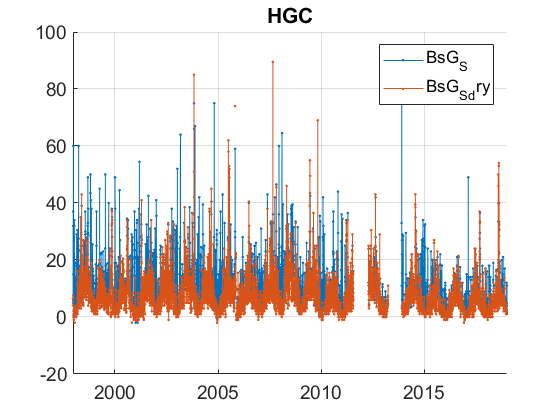

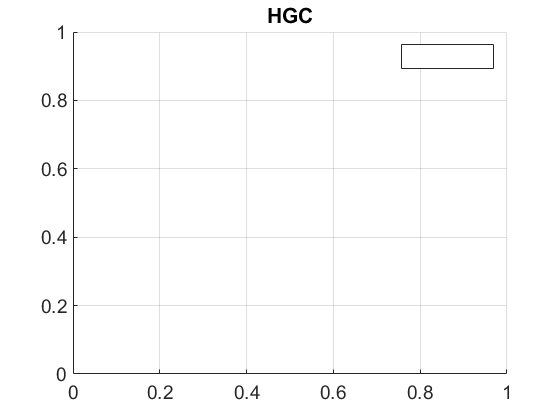

plotFigControl(HGC_rd,HGC_st.name);

% 1 size cut, ok
% sc: ok, max in summer, few negatives



% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE3=[467;530;660]*ones(1,4);
% % lambdaAE7=[370 470 520 590 660 880 950];
% % HGC_cal=compute_exp_SSA(HGC_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(HGC_cal,HGC_st.name);

%Questions:
%problems:
% holes from July 2011 to April 2012 and from April 2013 to november 2013: real holes 


HGC_tr=HGC_rd;
HGC_tr.y=year(HGC_tr.Time);
%eneleve une valeur de 2019
HGC_tr=HGC_tr(1:end-1,:);
% begin at the beginning of a year: 1998
% end: 2018
P=timerange('1998-01-01','2019-01-01');
HGC_tr=HGC_tr(P,:);

names=fieldnames(HGC_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    HGC_tr.(N{i})=[];
end



HGC_result= all_trend_STN(HGC_tr,HGC_st); 

HGC_result_D=HGC_result;